% ไม่มีข้อ 8 และ 11




%-----------Variable--------------

t = linspace(0,50e-3,1200);
Fs = 500;  % sample/sec
T = 1/Fs;
n = 0:80;
M = 12;
N =-M:M;
hn = zeros(1,length(N));
w = linspace(-3*pi,3*pi,1201);
Hw = zeros(1,length(w));

%----- omega--------
omegac = 0.2*pi;
omega0 = 0;
%-------------------

%--------------------------------


%--------------------1-------------------
x1 = -6+t*0%*ones(1,length(t));

x1 =     -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


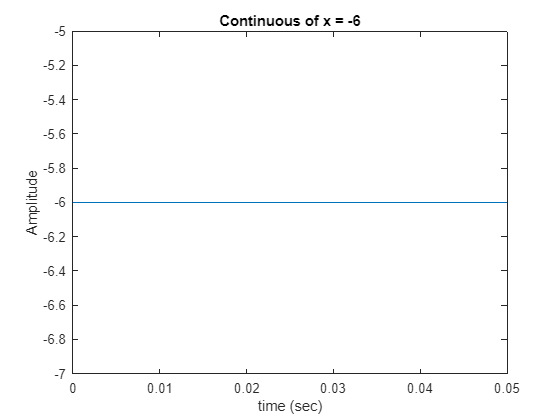

x2 = 2*sin(300*pi*t+pi/4);
x3 = 3*cos(200*pi*t);

%plot x1
figure(1);clf;
plot(t,x1)
title("Continuous of x = -6")
xlabel("time (sec)")
ylabel("Amplitude")

disp('Linear Frequency is 0 Hz')

Linear Frequency is 0 Hz


disp('Angular Frequency = 0 rad/sec')

Angular Frequency = 0 rad/sec


disp("Period = inf sec")

Period = inf sec


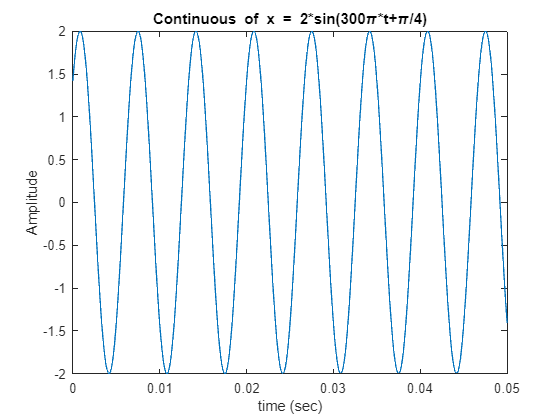


%plot x2
figure(2);clf;
plot(t,x2)
title("Continuous of x = 2*sin(300\pi*t+\pi/4)")
xlabel("time (sec)")
ylabel("Amplitude")

disp('Linear Frequency is 150 Hz')

Linear Frequency is 150 Hz


disp('Angular Frequency = 300\pi rad/sec')

Angular Frequency = 300\pi rad/sec


disp("Period = 0.0067 sec")

Period = 0.0067 sec


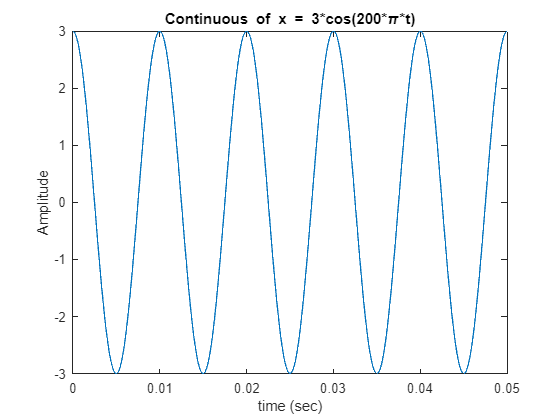


%plot x3
figure(3);clf;
plot(t,x3)
title("Continuous of x = 3*cos(200*\pi*t)")
xlabel("time (sec)")
ylabel("Amplitude")

disp('Linear Frequency is 100 Hz')

Linear Frequency is 100 Hz


disp('Angular Frequency = 200\pi rad/sec')

Angular Frequency = 200\pi rad/sec


disp("Period = 0.01 sec")

Period = 0.01 sec


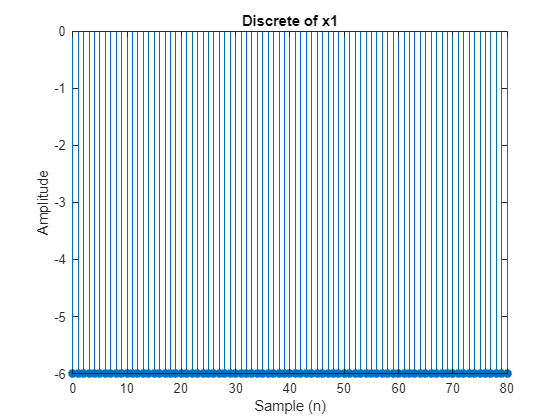

%----------------------------------------

%--------------------2-------------------
x1n = -6*ones(1,length(n));
x2n = 2*sin(300*pi*T*n+pi/4);
x3n = 3*cos(200*pi*T*n);

%plot x1n
figure(4);clf;
stem(n,x1n,"filled")
title("Discrete of x1")
xlabel("Sample (n)")
ylabel("Amplitude")

disp("Linear Frequency is 0 sam^-1")

Linear Frequency is 0 sam^-1


disp("Angular Frequency is 0 rad/sam")

Angular Frequency is 0 rad/sam


disp("Period is inf sample")

Period is inf sample


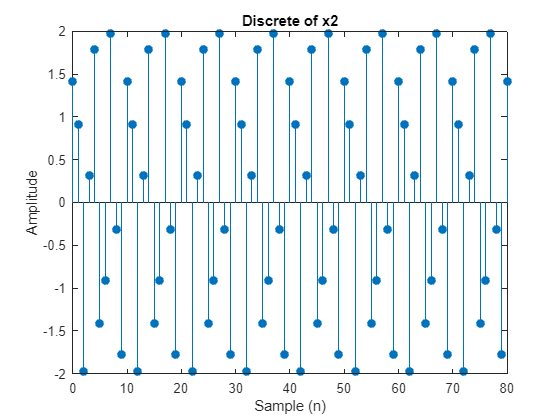


%plot x2n
figure(5);clf;
stem(n,x2n,'filled')
title("Discrete of x2")
xlabel("Sample (n)")
ylabel("Amplitude")

disp("Linear Frequency is 0.3 sam^-1")

Linear Frequency is 0.3 sam^-1


disp("Angular Frequency is 3/5*pi rad/sam")

Angular Frequency is 3/5*pi rad/sam


disp("Period is 5 sample")

Period is 5 sample


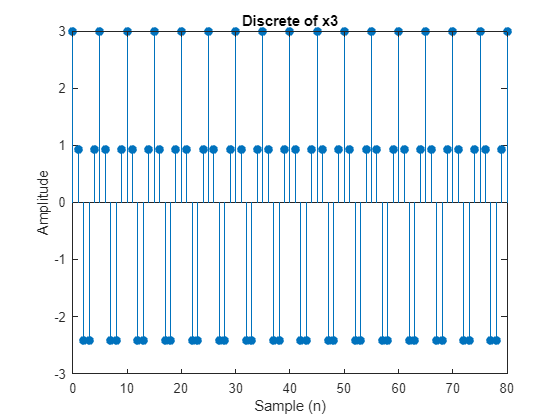


%plot x3n
figure(6);clf;
stem(n,x3n,'filled')
title("Discrete of x3")
xlabel("Sample (n)")
ylabel("Amplitude")

disp("Linear Frequency is 0.2 sam^-1")

Linear Frequency is 0.2 sam^-1


disp("Angular Frequency is 2/5*pi rad/sam")

Angular Frequency is 2/5*pi rad/sam


disp("Period is 5 sample")

Period is 5 sample


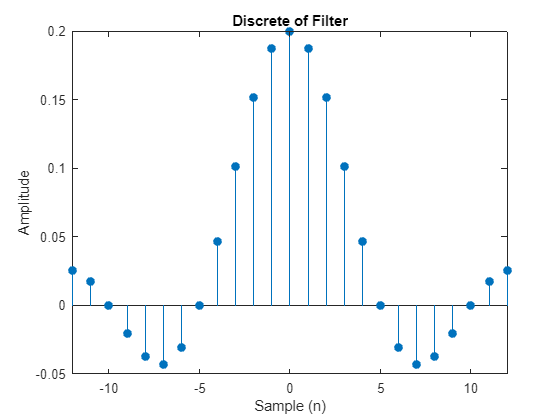

%-----------------------------------------

%------------------------3-----------------------
for i =1:length(N)
    if(N(i) == 0)
        if(cos(omega0) == 1)
            hn(i) = omegac/pi;
        else
            hn(i) = 2*omegac/pi;
        end
    else
        if(cos(omega0) == 1)
            hn(i) = (1/(pi*N(i)))*sin(omegac*N(i));%*cos(omega0*N(i));
        else
            hn(i) = (1/(pi*N(i)))*sin(omegac*N(i));%*cos(omega0*N(i));
        end  
    end
end

%plot h[n]
figure(7);clf;
stem(N,hn,'filled')
title("Discrete of Filter")
xlabel("Sample (n)")
ylabel("Amplitude")
xlim([-12 12])

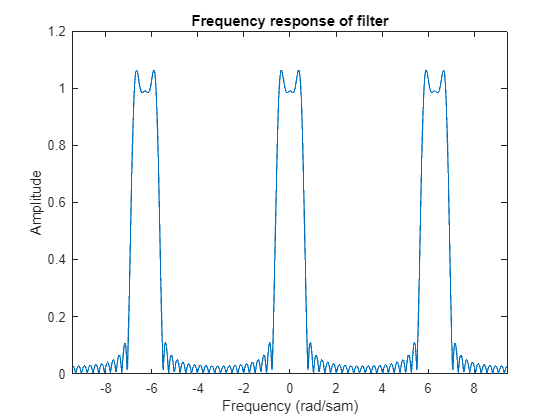

%------------------------------------------------

%-------------------------4-------------------------
for i = 1:length(w)
    Hw(i) = sum(hn.*exp(-1i*w(i)*N));
end

%plot freq res.
figure(8);clf;
plot(w,abs(Hw))
title("Frequency response of filter")
xlabel("Frequency (rad/sam)")
ylabel("Amplitude")
xlim([-3*pi 3*pi])

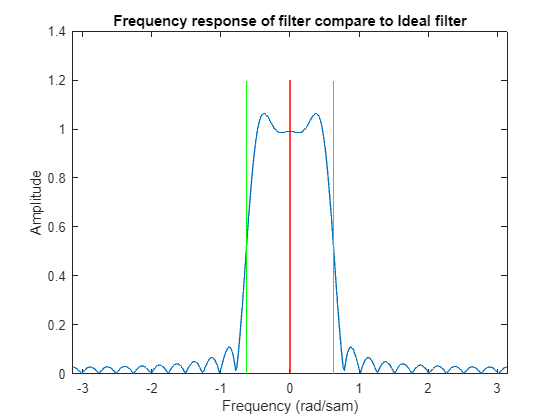


%plot compare to ideal filter
figure(9);clf;
A = axes;
plot(w,abs(Hw))
title("Frequency response of filter compare to Ideal filter")
ylabel("Amplitude")
xlabel("Frequency (rad/sam)")
xlim([-pi pi])
YL = get(A,'YLim');
line(omega0*[1 1],YL,'color','r')
line(omega0+omegac*[1 1],YL,'color','g')
line(omega0-omegac*[1 1],YL,'color','g')

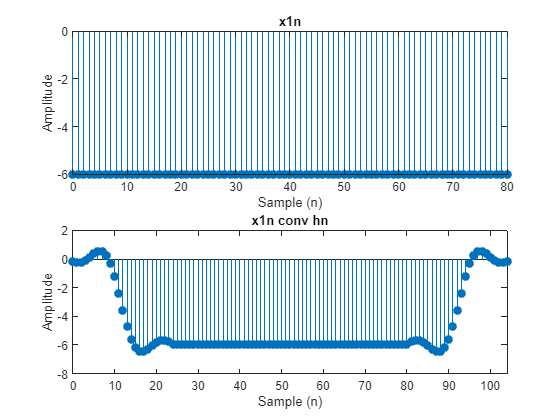


%-------------------------------------------------------

%----------------------------5---------------------------
n_p = 0:104;
y1n = my_conv(x1n,hn);

figure(10);clf;
subplot(2,1,1)
stem(n,x1n,"filled")
title("x1n")
ylabel("Amplitude")
xlabel("Sample (n)")

subplot(2,1,2)
stem(n_p,y1n,"filled")
title("x1n conv hn")
ylabel("Amplitude")
xlabel("Sample (n)")
xlim([0 104])

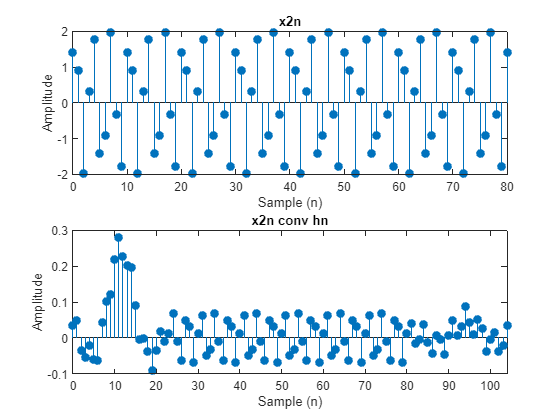

%---------------------------------------------------------

%----------------------------6---------------------------
y2n = my_conv(x2n,hn);

figure(11);clf;
subplot(2,1,1)
stem(n,x2n,"filled")
title("x2n")
ylabel("Amplitude")
xlabel("Sample (n)")

subplot(2,1,2)
stem(n_p,y2n,"filled")
title("x2n conv hn")
ylabel("Amplitude")
xlabel("Sample (n)")
xlim([0 104])

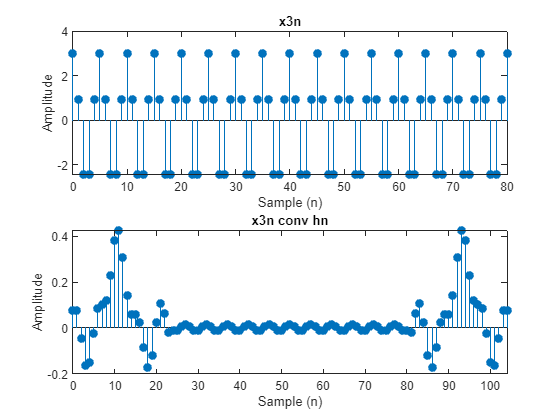

%---------------------------------------------------------

%----------------------------7---------------------------
y3n = my_conv(x3n,hn);

figure(12);clf;
subplot(2,1,1)
stem(n,x3n,"filled")
title("x3n")
ylabel("Amplitude")
xlabel("Sample (n)")

subplot(2,1,2)
stem(n_p,y3n,"filled")
title("x3n conv hn")
ylabel("Amplitude")
xlabel("Sample (n)")
xlim([0 104])

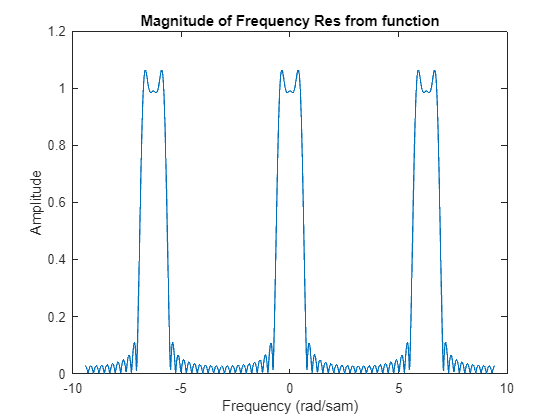

%---------------------------------------------------------

%-----------------------------------9 have function-------------------------
[hnn,Hwn,wn] = Nonrecursive(omega0,omegac,M);

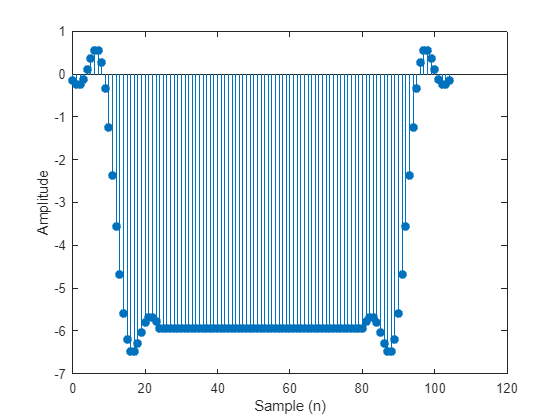

%----------------------------------------------------------------------------

%-----------------------------------10 have function-------------------------
yyy1 = FindOutput(x1n,hn);

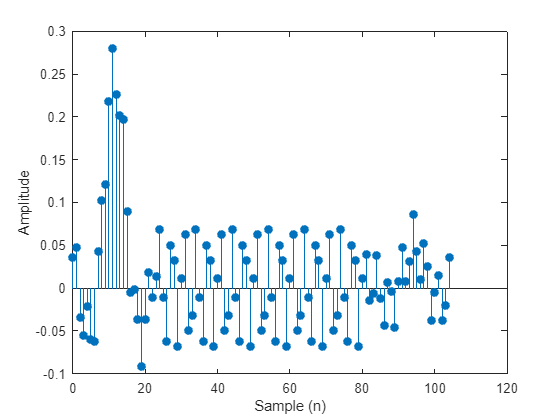

yyy2 = FindOutput(x2n,hn);

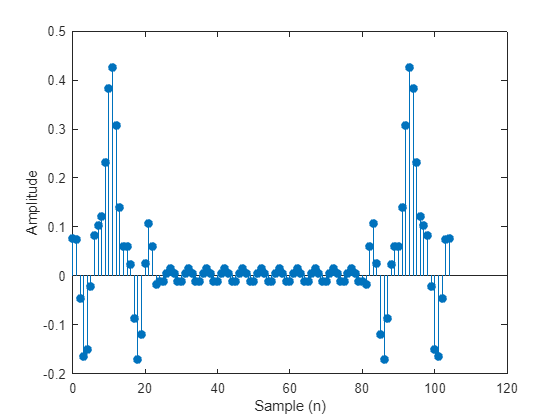

yyy3 = FindOutput(x3n,hn);

%----------------------------------------------------------------------------

function y = my_conv(x,h)
Nx = length(x);
Nh = length(h);
Ny = Nx+Nh-1;

y = zeros(1,Ny);
for i = 1:Ny
    for k = max(1,i-Nh+1):min(i,Nx)
        y(i) = y(i)+x(k)*h(i-k+1);
    end
end
end

%-------------------------------9--------------------------------
function [hn,Hw,w] = Nonrecursive(wo,wc,M)
Range = -M:M;
hn = zeros(1,length(Range));
w = linspace(-3*pi,3*pi,1201);
Hw = zeros(1,length(w));

for i =1:length(Range)
    if(Range(i) == 0)
        if(cos(wo) == 1)
            hn(i) = wc/pi;
        else
            hn(i) = 2*wc/pi;
        end
    else
        if(cos(wo) == 1)
            hn(i) = (1/(pi*Range(i)))*sin(wc*Range(i))*cos(wo*Range(i));
        else
            hn(i) = (2/(pi*Range(i)))*sin(wc*Range(i))*cos(wo*Range(i));
        end
    end
end

for i = 1:length(w)
    Hw(i) = sum(hn.*exp(-1i*w(i)*Range));
end

clf;
plot(w,abs(Hw))
title("Magnitude of Frequency Res from function")
ylabel("Amplitude")
xlabel("Frequency (rad/sam)")
end
%------------------------------------------------------------------

%------------------------------10----------------------------------
function yn = FindOutput(xn,hn)
Nxn = length(xn);
Nhn = length(hn);
Ny = Nxn+Nhn-1;
yn = zeros(1,Ny);

for i = 1:Ny
    for k = max(1,i-Nhn+1):min(i,Nxn)
        yn(i) = yn(i)+xn(k)*hn(i-k+1);
    end
end
n = 0:length(yn)-1;
clf;
stem(n,yn,"filled");
ylabel("Amplitude")
xlabel("Sample (n)")
end
%-------------------------------------------------------------------